clear;close all;clc;
load nspeech2.mat;
sound(nspeech2);

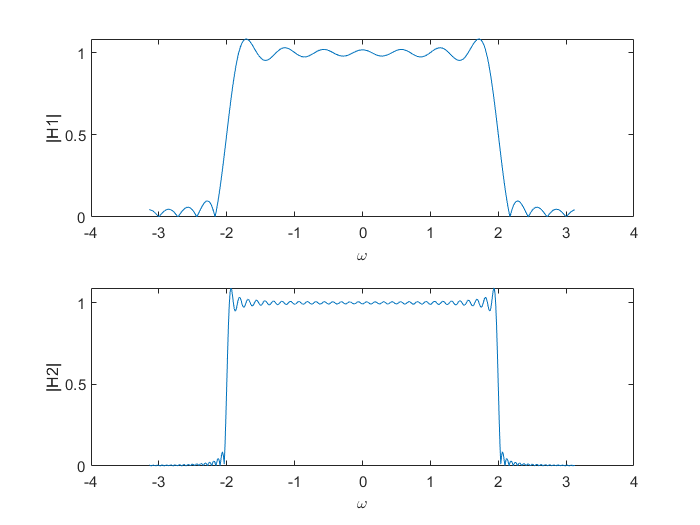


h1=LPFtrunc(21);
h2=LPFtrunc(101);

[X1,w1]=DTFT(h1,512);
[X2,w2]=DTFT(h2,512);

figure(1);
subplot(211);plot(w1,abs(X1));xlabel('\omega');ylabel('|H1|');
subplot(212);plot(w2,abs(X2));xlabel('\omega');ylabel('|H2|');

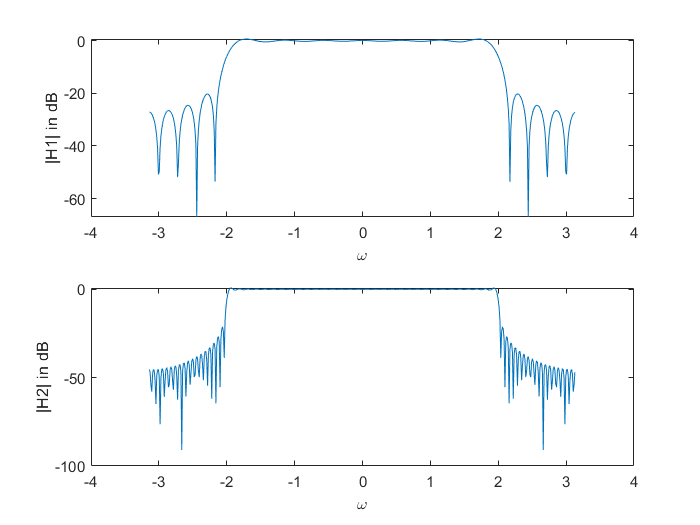


figure(2);
subplot(211);plot(w1,20*log10(abs(X1)));xlabel('\omega');ylabel('|H1| in dB');
subplot(212);plot(w2,20*log10(abs(X2)));xlabel('\omega');ylabel('|H2| in dB');

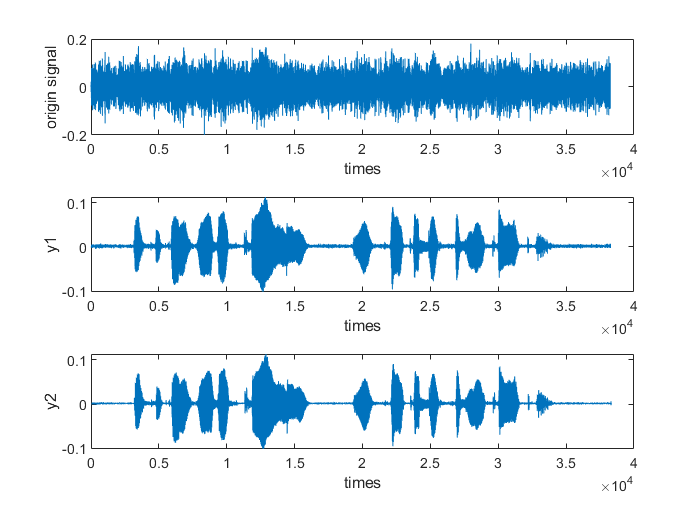

figure(3);
y1=conv(h1,nspeech2);

% sound(y1);
y2=conv(h2,nspeech2);
subplot(311);plot(nspeech2);xlabel('times');ylabel('origin signal');
subplot(312);plot(y1);xlabel('times');ylabel('y1');
subplot(313);plot(y2);xlabel('times');ylabel('y2');

% sound(y2);
